# Display Several Geographic Bubble Charts Centered Within Specified Limits

This example shows how to create two geographic bubble charts with the same map limits.

Read Lyme Disease sample data into the workspace.

counties = readtable('counties.xlsx');

Create a geographic bubble chart that plots the occurrences of Lyme disease in New England counties.

gb = geobubble(counties,'Latitude','Longitude','SizeVariable','Cases2010');

Pan and zoom the map until you see only the states in northern New England: Vermont, New Hampshire, and Maine.

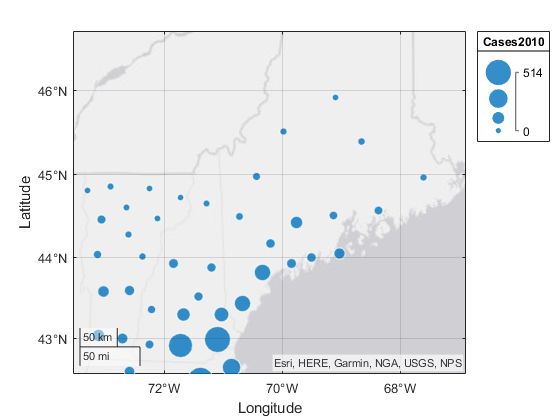 

Get the new limits of the map using the command `[nlat nlon] = geolimits(gb)`. Get the new zoom level as well using the command  `nzoom = gb.ZoomLevel`. Store the latitude, longitude, and zoom level of the new map limits.

nlat = [42.5577   46.6921];
nlon = [-73.5500  -66.8900];
nzoom = 6.3747;

Create another map with Lyme disease occurrence data for 2011 and set the map limits and zoom level to match the first chart.

figure
gb2 = geobubble(counties,'Latitude','Longitude','SizeVariable','Cases2011');
[n2lat n2lon] = geolimits(gb2,nlat,nlon);
gb2.ZoomLevel = nzoom;

*Copyright 2012 The MathWorks, Inc.*